In =      1     0     0
     0     1     0
     0     0     1


$$A = \left(\begin{array}{ccc} 0 & 1 & 0\\ \frac{{X_{3}}^{2}\,c}{{X_{1}}^{2}\,m} & 0 & -\frac{2\,X_{3}\,c}{X_{1}\,m}\\ 0 & 0 & -\frac{R}{L} \end{array}\right)$$

$$B = \left(\begin{array}{c} 0\\ 0\\ \frac{1}{L} \end{array}\right)$$

C =      1     0     0


$$X = \left(\begin{array}{ccc} s & -1 & 0\\ -\frac{{X_{3}}^{2}\,c}{{X_{1}}^{2}\,m} & s & \frac{2\,X_{3}\,c}{X_{1}\,m}\\ 0 & 0 & s+\frac{R}{L} \end{array}\right)$$

$$Y = \begin{array}{l} \left(\begin{array}{ccc} -\frac{{X_{1}}^{2}\,m\,s}{\sigma_{1}} & -\frac{{X_{1}}^{2}\,m}{\sigma_{1}} & \frac{2\,L\,X_{1}\,X_{3}\,c}{\sigma_{1}\,\left(R+L\,s\right)}\\ -\frac{{X_{3}}^{2}\,c}{\sigma_{1}} & -\frac{{X_{1}}^{2}\,m\,s}{\sigma_{1}} & \frac{2\,L\,X_{1}\,X_{3}\,c\,s}{\sigma_{1}\,\left(R+L\,s\right)}\\ 0 & 0 & \frac{L}{R+L\,s} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={X_{3}}^{2}\,c-{X_{1}}^{2}\,m\,s^{2} \end{array}$$

$$q1 = \frac{R^{2}\,g^{2}\,m}{V^{2}\,c}$$

$$q2 = -\frac{2\,R\,g}{V}$$

$$q3 = -\frac{R}{L}$$

$$q4 = \frac{1}{L}$$

$$q1 = \frac{7.1e+6}{V^{2}}$$

$$q2 = -\frac{540.0}{V}$$

$$q3 = -\frac{554}{13}$$

$$q4 = \frac{20}{13}$$

v =    93.5000   94.5000   95.5000   96.5000   97.5000   98.5000   99.5000  100.5000  101.5000  102.5000  103.5000  104.5000  105.5000  106.5000  107.5000  108.5000  109.5000  110.5000  111.5000  112.5000  113.5000  114.5000  115.5000  116.5000  117.5000  118.5000  119.5000  120.5000  121.5000  122.5000  123.5000  124.5000  125.5000  126.5000


x =   812.1479  795.0505  778.4874  762.4366  746.8771  731.7890  717.1536  702.9529  689.1698  675.7882  662.7926  650.1683  637.9012  625.9781  614.3862  603.1133  592.1478  581.4787  571.0953  560.9877  551.1460  541.5610  532.2239  523.1262  514.2598  505.6170  497.1902  488.9723  480.9565  473.1362  465.5051  458.0571  450.7865  443.6876


y =    -5.7754   -5.7143   -5.6545   -5.5959   -5.5385   -5.4822   -5.4271   -5.3731   -5.3202   -5.2683   -5.2174   -5.1675   -5.1185   -5.0704   -5.0233   -4.9770   -4.9315   -4.8869   -4.8430   -4.8000   -4.7577   -4.7162   -4.6753   -4.6352   -4.5957   -4.5570   -4.5188   -4.4813   -4.4444   -4.4082   -4.3725   -4.3373   -4.3028   -4.2688


z = 0

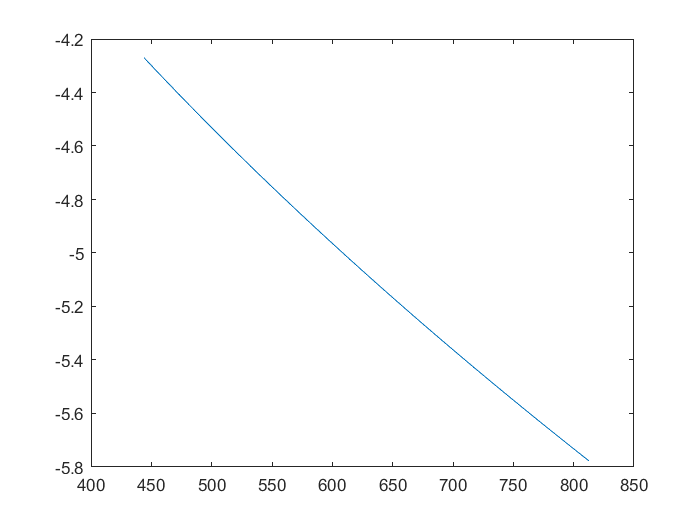

$$A1 = \left(\begin{array}{cccc} 0 & -1 & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & \frac{1778005856507873}{2199023255552} & 0 & -\frac{3272178213612933}{562949953421312}\\ 0 & 0 & 0 & -\frac{554}{13} \end{array}\right)$$

$$A2 = \left(\begin{array}{cccc} 0 & -1 & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & \frac{7770793081750855}{17592186044416} & 0 & -\frac{2418566505713907}{562949953421312}\\ 0 & 0 & 0 & -\frac{554}{13} \end{array}\right)$$

B =          0
         0
         0
    1.5385



 Solver for LMI feasibility problems L(x) < R(x)
    This solver minimizes  t  subject to  L(x) < R(x) + t*I
    The best value of t should be negative for feasibility

 Iteration   :    Best value of t so far 
 
     1                        0.199919
     2                        0.043006
     3                        0.017008
     4                    7.378287e-03
     5                    7.378287e-03
     6                    6.085784e-03
     7                    6.085784e-03
     8                    1.603291e-03
     9                    -1.806200e-04

 Result:  best value of t: -1.806200e-04
          f-radius saturation:  0.004% of R =  1.00e+09
 


S = 	1.0e+03 *

    0.0000    0.0000   -0.0000    0.0013
    0.0000    0.0001   -0.0006    0.0071
   -0.0000   -0.0006    0.0153   -0.0195
    0.0013    0.0071   -0.0195    1.6544


R = 	1.0e+04 *

    0.0038    0.0201    0.2033    4.4647


K = 	1.0e+05 *

   -1.2824    0.7460    0.0268   -0.0016


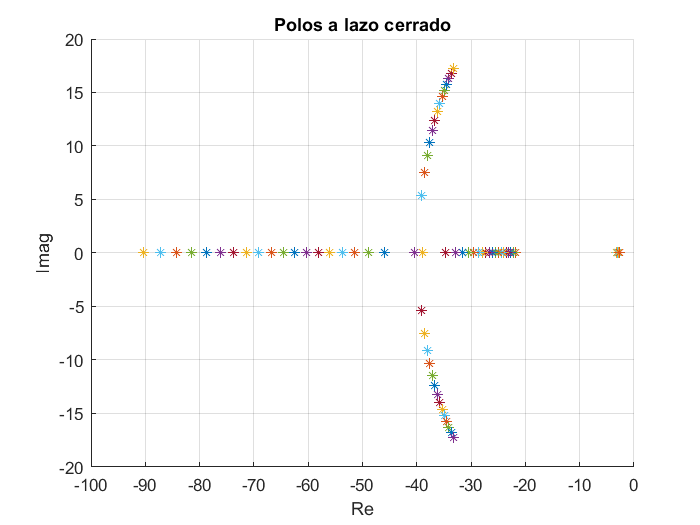

% definimos la variable compleja s
syms s c m R g L V x1 x2 x3 X1 X2 X3 % X mayuscula es para el punto de equilibrio; c = constante; m = masa ; R = resistencia; L = inductancia; V = tensión; g = gravedad
% In
In =  [1 0 0;0 1 0;0 0 1]
% A
A = [0 1 0; (c*X3^2)/(m*X1^2) 0 (-2*c*X3)/(m*X1);0 0 -R/L]
% B
B = [0;0;1/L]
% C 
C = [1 0 0]
% sIn - A 
X = s*In - A
% inversa 
Y = inv(X)

% Se sustituyeron los valores netos de
% http://dx.doi.org/10.1080/00207729608929322 
% R = 27.7 Ohm , L = 0.65 H, c = 1.24 * 10^-4 Nm^2 A^2, M =11.87gr=0.01187Kg, 
% se variara la tensión del punto de equilibrio de 106,02V a 111,97V, lo
% cual deberia permitir tener un control robusto de la planta para
% posiciones entre 15,6mm a 17.4mm

%q1 A(2,1) 
q1 =  (c*(V/R)^2)/(m*(((c*V^2)/(m*g*R^2)))^2)
%q2 A(2,3)
q2 = -1 * ((2*V/R*c)/(m*(c*V^2)/(m*g*R^2)))
%q3 A(3,3)
q3 = -R/L
%q4 B(3,1)
q4 = 1/L

% Sustituimos los valores por defecto 

q1 = vpa(subs(q1, [c g m R], [1.24e-4 9.81 0.01187 27.7]), 2)

q2 = vpa(subs(q2, [c g m R], [1.24e-4 9.81 0.01187 27.7]), 2)

q3 = subs(q3, [R L], [27.7 0.65])

q4 = subs(q4, L, 0.65)
% La variación en el tiempo de q1 y q2 en el tiempo sera de un 5% arriba y
% hacia abajo (definición del politopo)

v1 = 110 *0.85;
v2 = 110 *1.15;

%q4 pertenece a:


figure
for  v=v1:1:v2
    q1V = subs(q1, V, v);
    q2V = subs(q2, V, v);
    A=[0 1 0; q1V 0 q2V; 0 0 q3];
    p=eig(A);
    hold on
    plot(real(p(1)),imag(p(1)),'*')
    plot(real(p(2)),imag(p(2)),'*')
    plot(real(p(3)), imag(p(3)), '*')
end
grid
xlabel('Re'), ylabel('Imag'), title('Polos a lazo abierto')
hold off



% politopo 
v=v1:1:v2

x=7.1e+6./v.^2
y=-540./v
z= 0
r=plot(x,y);



% % Creamos la desigualdad lineal matricial 
% 
% 
% Realimentación de estado + reubicación de polos en región R(Alfa,Ro) 
% Theta = 0.

% Planta
% y = 0.0156m
A1=[0 -1 0 0;0 0 1 0;0 double(subs(q1, V, v1)) 0 double(subs(q2, V, v1));0 0 0 q3]
% y = 0.0174m
A2=[0 -1 0 0;0 0 1 0;0 double(subs(q1, V, v2)) 0 double(subs(q2, V, v2));0 0 0 q3]

B=[0; 0; 0; double(vpa(q4,2))]

% Especificaciones región reubicación de polos
Alfa=1;

% Creación sistema LMI
setlmis([])

% Variables LMIs
S=lmivar(1,[4 1]); % S(3,3) simétrica, 3x3 porque A es de 3x3 
R=lmivar(2,[1 4]); % R(1,2) arbitraria, 1x3 porque B es de 1x3

% S > 0

lmiterm([-1 1 1 S],1,1);

% Restricciones asociadas al parámetro Alfa

% 𝑨𝑺 + 𝑺𝑨𝑻 + 𝑩1S + 𝑹𝑩1 + 𝟐𝜶𝑺 < 𝟎
lmiterm([2 1 1 S],A1,1,'s');
lmiterm([2 1 1 R],B,1,'s');
lmiterm([2 1 1 S],2*Alfa,1);

% 𝑨𝑺 + 𝑺𝑨𝑻 + 𝑩2R + 𝑹𝑩2 + 𝟐𝜶𝑺 < 𝟎
lmiterm([3 1 1 S],A2,1,'s');
lmiterm([3 1 1 R],B,1,'s');
lmiterm([3 1 1 S],2*Alfa,1);



% Ejecución del solver
LMISYS=getlmis;
[tmin,xfeas]=feasp(LMISYS);

% Solución
S=dec2mat(LMISYS,xfeas,S)
R=dec2mat(LMISYS,xfeas,R)

K=R/(S)



% Polos a lazo cerrado del sistema  politópico

figure
for  v=v1:1:v2
    q1F = subs(q1, V, v);
    q2F = subs(q2, V, v);
    A=[0 -1 0 0;0 0 1 0;0 q1F 0 q2F;0 0 0 q3];
    p=eig(A + B*K);
    hold on
    plot(real(p(1)),imag(p(1)),'*')
    plot(real(p(2)),imag(p(2)),'*')
    plot(real(p(3)), imag(p(3)), '*')
end
grid
xlabel('Re'), ylabel('Imag'), title('Polos a lazo cerrado')
hold off


